# Sample 4-2

## 線形シフト不変システム

相関と畳み込み

画像処理特論

村松 正吾 

動作確認: MATLAB R2020a

## Linear shift-invariant systems

Correlation and convolution

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2020a

### 準備

(Preparation)

close all

### 入力信号 $\{u[n]\}_n
$ 

(Input signal $\{u[n]\}_n
$)

% Input x[n]
u = [1 2 3];

### フィルタカーネル $\{w[n]\}_n
$ 

(Filter kernel $\{w[n]\}_n
$)

% Filter kernel w[n]
w = [-1 0 1];

### 相互相関$\{x[n]\}_n
$ 

(Cross-correlation $\{x[n]\}_n
$)

相互相関 (Cross-correlation) 

        
$$\{x[n]\}_n=\sum_{k=-\infty}^{\infty}u[k]\{w[n+k]\}_n
$$


% Output x[n]
x = xcorr(u,w);
ndiff = length(u)-length(w);
% Extract the significant subsequence
if ndiff <= 0
    x = x(1:end+ndiff)
else
    x = x(ndiff+1:end)
end

x =     1.0000    2.0000    2.0000   -2.0000   -3.0000


### 線形シフト不変システムの出力応答$\{v[n]\}_n
$ 

(The linear shift-invariant system response $\{v[n]\}_n
$)

畳み込み演算 (Convolution)

        
$$\{v[n]\}_n=\{h[n]\}_n \ast \{u[n]\}_n = \sum_{k=-\infty}^{\infty}u[k]\{h[n-k]\}_n
$$


フィルタカーネル $\{w[n]\}_n$の反転 (Reversing the filter kernel  $\{w[n]\}_n$.)

        
$$\{h[n]\}_n=\{w[-n]\}_n$$


% Flip the elements in w[n]
h = flip(w)

h =      1     0    -1


$\{h[n]\}_n$をインパルス応答とした畳み込み演算． (A convolutional operation with $\{h[n]\}_n$ as the impulse response.)

% Output y[n]
v = conv(h,u)

v =      1     2     2    -2    -3


### 入出力のプロット

(Plot of the input and output)

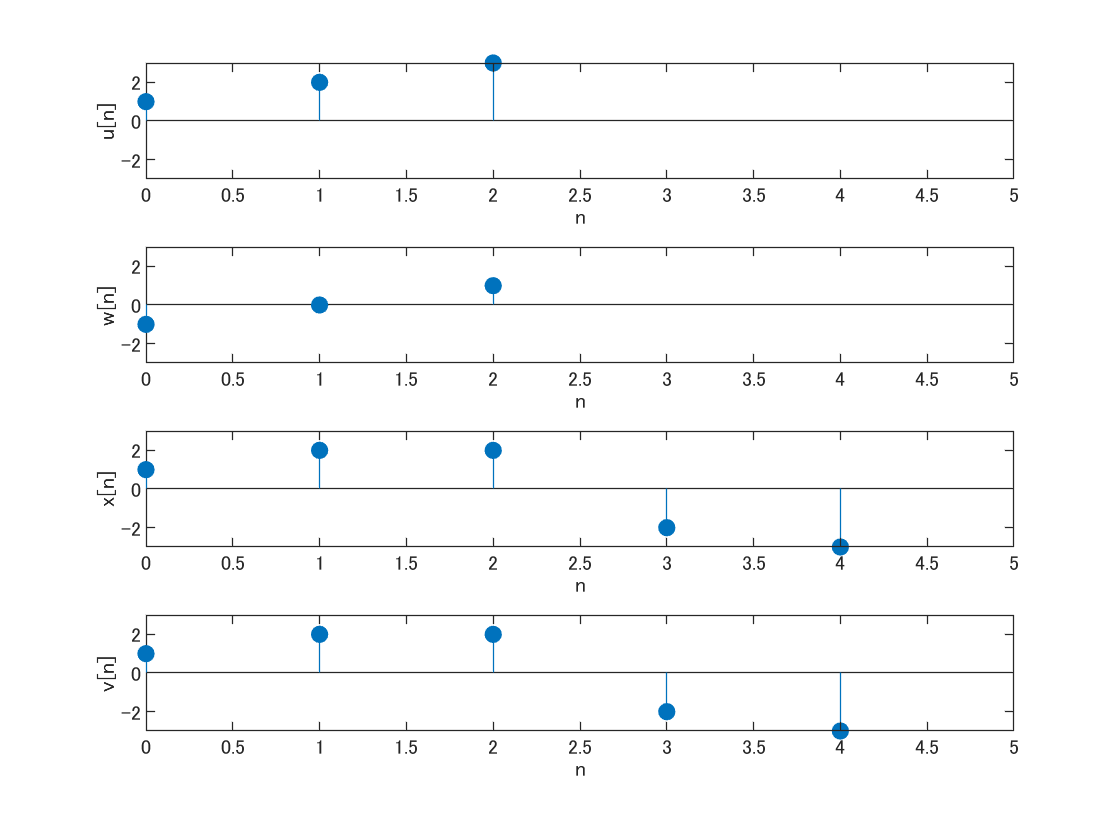

% Lengths of u, h, x and v
nu = length(u);
nw = length(w);
nx = length(x);
nv = length(v);

figure(1)
amax = max(max(abs(u)),max(abs(x)));
%% u[n]
subplot(4,1,1)
stem(0:nu-1,u,'filled')
axis([0 nx -amax amax])
xlabel('n')
ylabel('u[n]')

%% w[n]
subplot(4,1,2)
stem(0:nw-1,w,'filled')
axis([0 nx -amax amax])
xlabel('n')
ylabel('w[n]')

%% x[n]
subplot(4,1,3)
stem(0:nx-1,x,'filled')
axis([0 nx -amax amax])
xlabel('n')
ylabel('x[n]')

%% v[n]
subplot(4,1,4)
stem(0:nv-1,v,'filled')
axis([0 nx -amax amax])
xlabel('n')
ylabel('v[n]')

### 平均自乗誤差(MSE)による評価

(Evaluation in terms of the mean squared errors (MSE))

        
$$\mathrm{MSE}(\{x[n]\}_n,\{v[n]\}_n) \colon =\frac{1}{\left|\Omega\right|}\sum_{n\in\Omega}\left|x[n]-v[n]\right|^2,$$


ただし， $\Omega$は添え字集合， $|\Omega|$ は添え字の数．(where $\Omega$ denotes the index set and $|\Omega|$ means the cardinality.)

% Comparison between x and v
mse(x,v)

ans = 4.1908e-32

### 2変量フィルタリングと畳み込み

(Bivariate filtering and convolution)

インパルス信号 (Impulse signal)

        
$$\delta[\mathbf{n}] = \left\{\begin{array}{ll} 1 & \mathbf{n}=\mathbf{0} \\ 0 & \mathrm{otherwise}\end{array}\right.$$


% Bivariate impulse signal
D = 1

D = 1

フィルタカーネル $\{f[\mathbf{n}]\}_{\mathbf{n}}$の設定 (Setting of filter kernel $\{f[\mathbf{n}]\}_{\mathbf{n}}$)

% Definition of filter kernel f[n]
f = reshape(1:9,[3 3])

f =      1     4     7
     2     5     8
     3     6     9


関数IMFILTERのインパルス応答はフィルタカーネル$\{f[\mathbf{n}]\}_{\mathbf{n}}$の各軸反転となる．

(The impulse response of function IMFILTER is an inversion of each axis of the filter kernel $\{f[\mathbf{n}]\}_{\mathbf{n}}$.)

'full' オプションはクリッピングをせずに出力する．(The 'full' option outputs without clipping.)

% Impulse response of IMFILTER
imfilter(D,f,'full') 

ans =      9     6     3
     8     5     2
     7     4     1


フィルタカーネル$\{f[\mathbf{n}]\}_{\mathbf{n}}$を各軸反転 (Flip the filter kernel $\{f[\mathbf{n}]\}_{\mathbf{n}}$ on each axis.)

% Flipping filer kernel f[n]
h = rot90(f,2)

h =      9     6     3
     8     5     2
     7     4     1


関数IMFILTERの'conv'オプションは2番目の引数をインパルス応答$\{h[\mathbf{n}]\}_{\mathbf{n}}$として畳み込みを行う．

(The 'conv' option of function IMFILTER performs convolution with the second argument as an impulse response.)

% IMFILTER with the options 'conv' and 'full'
imfilter(D,h,'conv','full')

ans =      9     6     3
     8     5     2
     7     4     1


オプション'full'のみの結果と同じことが確かめられる．(It can be verified that the result is the same as for the option 'full' only.)

関数IMFILTERの'conv'と'full'オプションは関数CONV2と同等の機能をもつ．(The 'conv' and 'full' options of the function IMFILTER have the same functions as those of the function CONV2.)

conv2(D,h)

ans =      9     6     3
     8     5     2
     7     4     1


### **画像フィルタリングの例**

(Example of image filtering)

サンプル画像の読み込み (Reading a sample image)

% Reading image 'cameraman.tif' as double type.
I = im2double(imread('cameraman.tif'));
figure(2)
subplot(2,2,1)
imshow(I)
title('(a) Original')

水平Prewittカーネルの生成

(Generate a horizontal Prewitt kernel)

% Generate the horizontal Prewitt kernel
f = fspecial('prewitt').'

f =      1     0    -1
     1     0    -1
     1     0    -1


オプションなしIMFILTER 実行

(IMFILTER without any option)

% IMFILTER w/o any option
J = imfilter(I,f);
subplot(2,2,2)
imshow(J+.5)
title('(b) Prewitt w/o any option ')

'corr'オプション付きIMFILTER 実行

(IMFILTER without the option 'corr')

% IMFILTER w the option 'corr' (Correlation mode)
K = imfilter(I,f,'corr');
subplot(2,2,3)
imshow(K+.5)
title(sprintf('(c) Prewitt w "corr" (MSE w (b): %4.2f)',mse(J,K)))

フィルタカーネル$\{f[\mathbf{n}]\}_{\mathbf{n}}$を各軸反転 (Flip the filter kernel $\{f[\mathbf{n}]\}_{\mathbf{n}}$ on each axis.)

% Flipping filer kernel f[n]
h = rot90(f,2)

h =     -1     0     1
    -1     0     1
    -1     0     1


'conv'オプション付きIMFILTER 実行

(IMFILTER without the option 'conv')

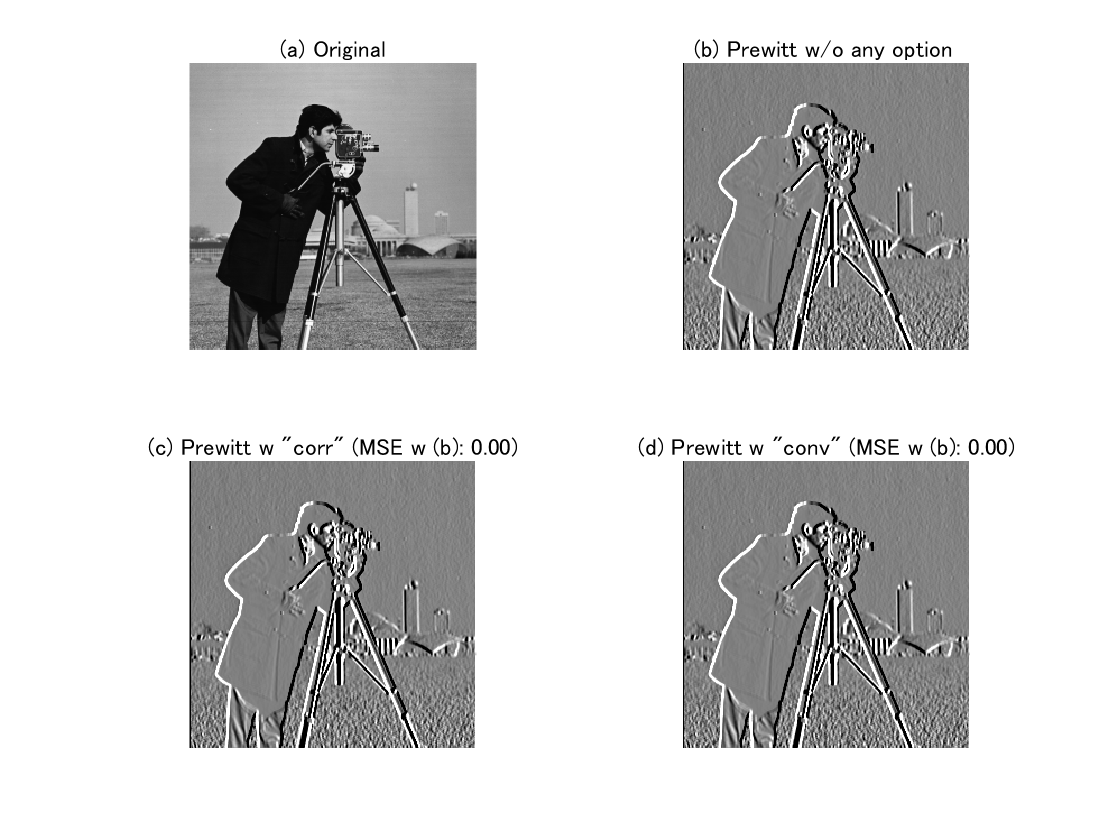

% IMFILTER w the option 'conv' (Convolution mode)
L = imfilter(I,h,'conv');
subplot(2,2,4)
imshow(L+.5)
title(sprintf('(d) Prewitt w "conv" (MSE w (b): %4.2f)',mse(J,L)))

(b),(c),(d)の結果はすべて同じ．(The results in (b), (c), and (d) are all the same.)

© Copyright, Shogo MURAMATSU, All rights reserved.